addpath('./datos')
addpath('./funciones/')

% Cargo el fichero .wav
audio1="test_period_70.wav";
audio2 = "Afonso_8khz.wav";
audio3="Gala_8khz.wav";
[s fs_period] = audioread(audio1);
[s2 fs_period2] = audioread(audio2);
[s3 fs_period3] = audioread(audio3);
s=s';
s2=s2';
s3=s3';

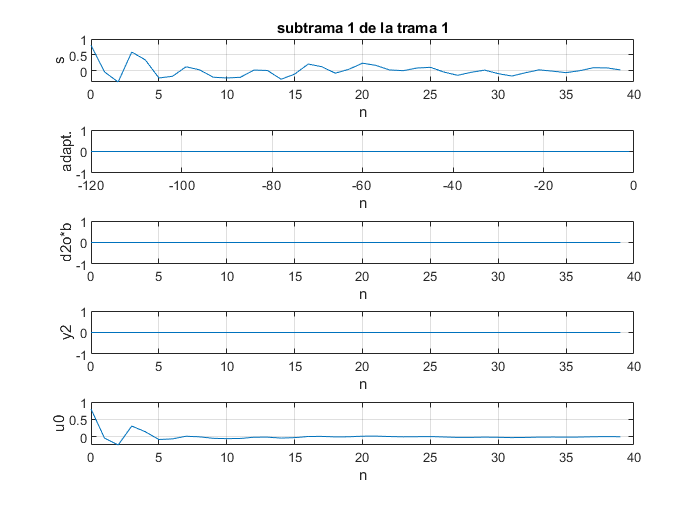

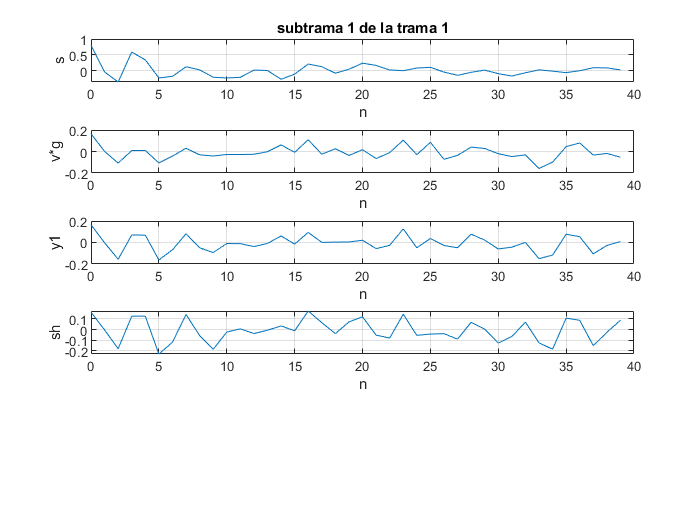

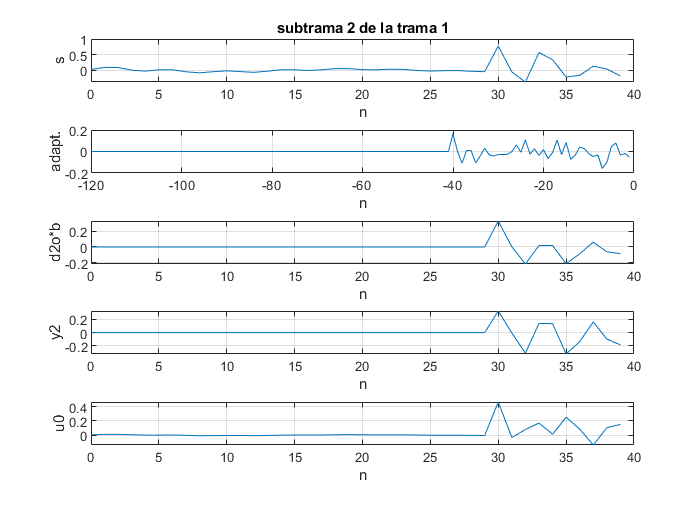

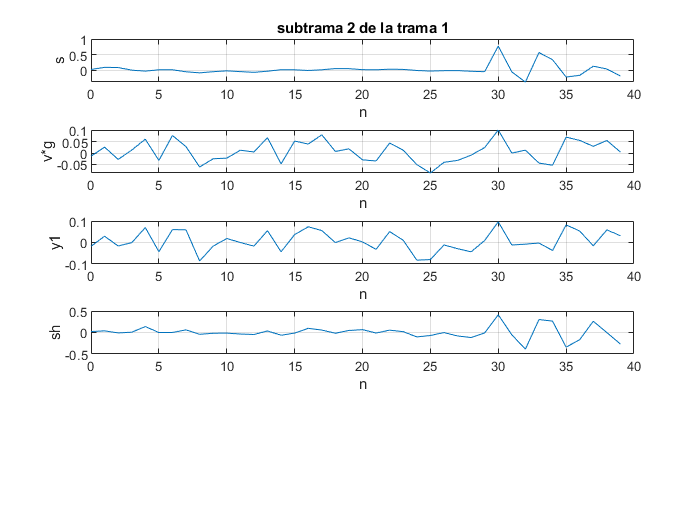

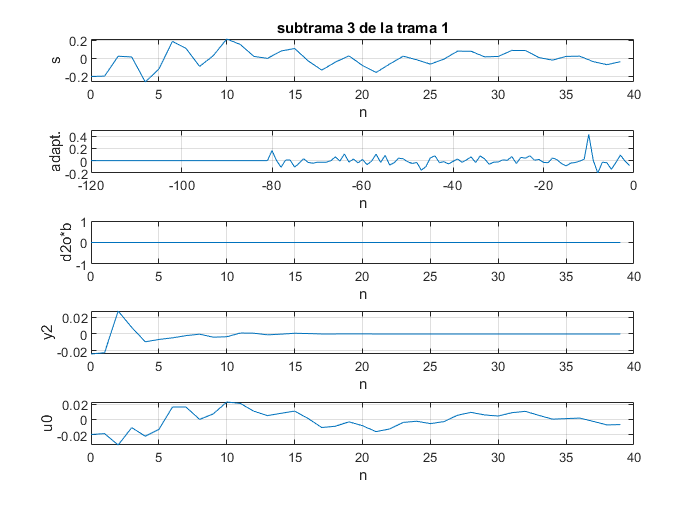

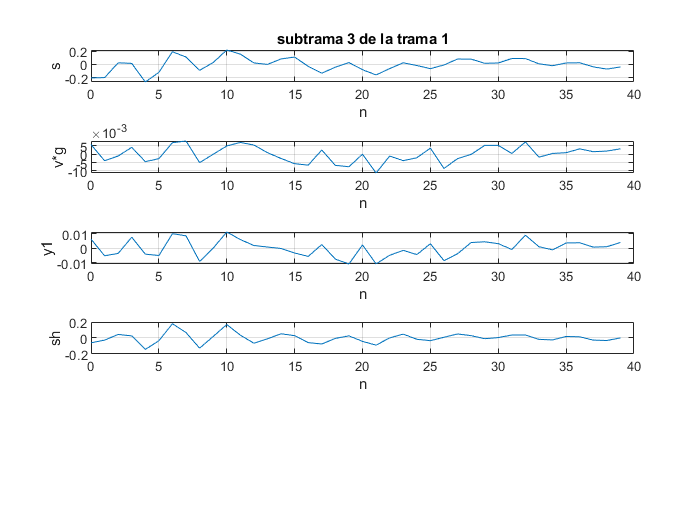

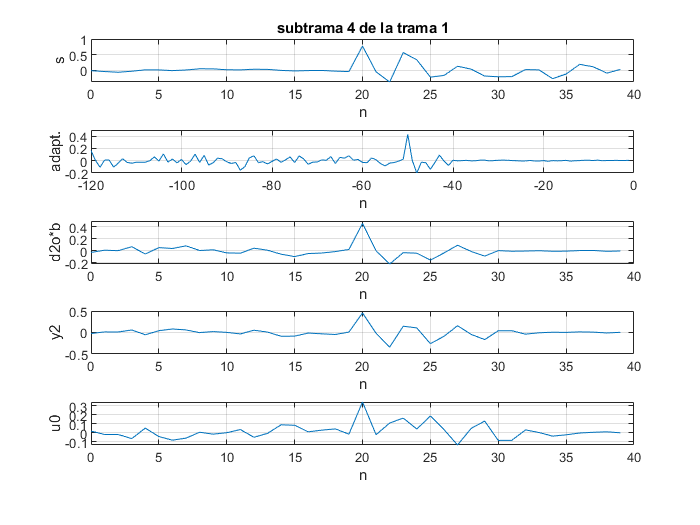

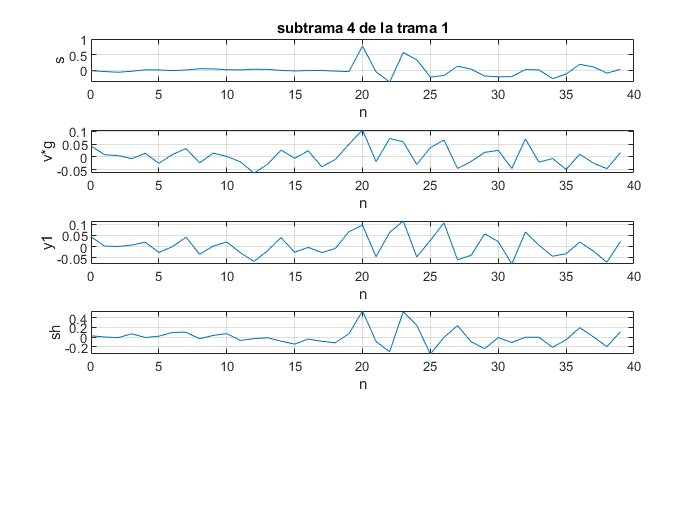

sh =     0.1647   -0.0036   -0.1822    0.1264    0.1270   -0.2319   -0.1201    0.1428   -0.0568   -0.1876   -0.0242    0.0066   -0.0385   -0.0062    0.0345   -0.0118    0.1757    0.0653   -0.0383    0.0723    0.1210   -0.0527   -0.0810    0.1456   -0.0550   -0.0431   -0.0390   -0.0914    0.0685    0.0040   -0.1276   -0.0661    0.0707   -0.1256   -0.1865    0.1080    0.0875   -0.1525   -0.0260    0.0882    0.0216    0.0385   -0.0096    0.0071    0.1384   -0.0014    0.0008    0.0612   -0.0411   -0.0174


B =          0    1.9935   -1.3081    1.0703   -0.2836    1.0645   -0.7242    0.9721    1.0051   -0.0482    0.9972   -0.3706    1.0314    0.6488    1.0560    1.0147   -0.1012    0.9950   -0.2619    1.0068    0.2955    0.9928    1.0088    0.6690    0.9911   -0.6008    1.0060   -0.6504    1.0024    0.9983    1.1116    1.0007    0.7667    1.0044    0.9552    0.9984    0.9938    0.8687    1.0001    0.9588    1.0079   -0.9291    0.9994    1.0037    0.9178    0.9947    0.5770    0.9906    0.3820    1.0049


G =    -0.0766    0.0383   -0.0049   -0.0396    0.0031   -0.0348   -0.0014    0.0244    0.0139    0.0042    0.0121    0.0026   -0.0166   -0.0035   -0.0117    0.0070    0.0067   -0.0082    0.0033    0.0056   -0.0016    0.0050   -0.0027   -0.0030    0.0029    0.0020    0.0022    0.0013   -0.0039    0.0019    0.0027    0.0021   -0.0013   -0.0034    0.0010    0.0022   -0.0023   -0.0018   -0.0019   -0.0012    0.0051   -0.0021    0.0064    0.0016    0.0049    0.0061    0.0014    0.0048    0.0014    0.0034


AK =     1.0000    0.0290    0.4507   -0.6715   -0.2534   -0.3550    0.3887    0.3023    0.4194   -0.0250   -0.0021    1.0000    0.0035    0.4492   -0.6758   -0.2359   -0.3444    0.4036    0.2973    0.4154   -0.0360    0.0020    1.0000    0.0359    0.4515   -0.6797   -0.2623   -0.3591    0.4052    0.3177    0.4319   -0.0256   -0.0054    1.0000    0.0325    0.4518   -0.6657   -0.2460   -0.3404    0.3920    0.2798    0.3856   -0.0233   -0.0247    1.0000   -0.0093    0.4515   -0.6880   -0.2348   -0.3389


Tv =      3   -47     3   -47   -36   -47   -36   -47   -47   -36   -47   -37   -47   -26   -47   -47   -36   -47   -36   -47   -26   -47   -47   -47   -47   -36   -47   -37   -47   -47   -47   -47   -47   -47   -47   -47   -47   -47   -47   -47   -47   -20   -47   -47   -47   -47   -47   -47   -26   -47


indv =    378   205   438    91   148   307   310   103    81   416   411   200   226   298   284   409   491    97   230   277    35    82   501   197   493   230   272   391   330   134    56   291    21   193   473   140   118   336   402   465     7   200   115   395   378   507   114   115   335   430


bitsPorMuestra = 0.9875

p = 10;
Lsubtrama = 40;
Ltrama =Lsubtrama * 4;

[sh,B,G,AK,Tv,indv, bitsPorMuestra] = celp(s,Ltrama,Lsubtrama,p)

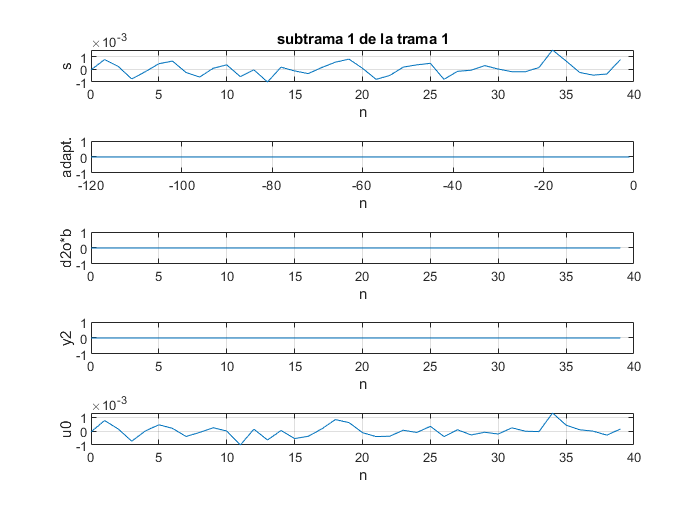

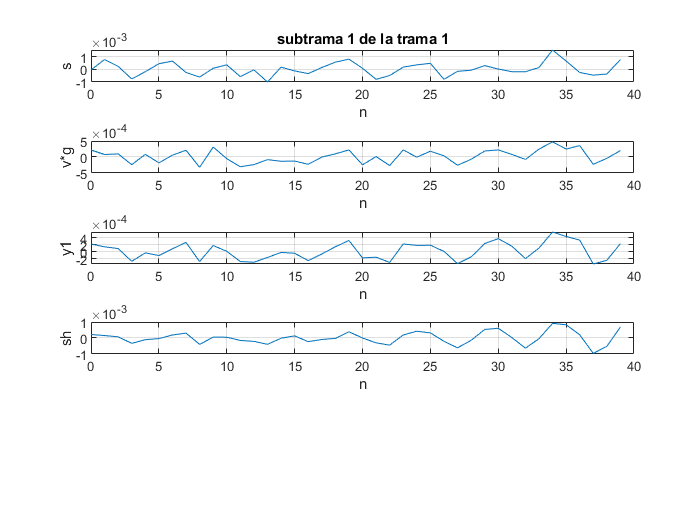

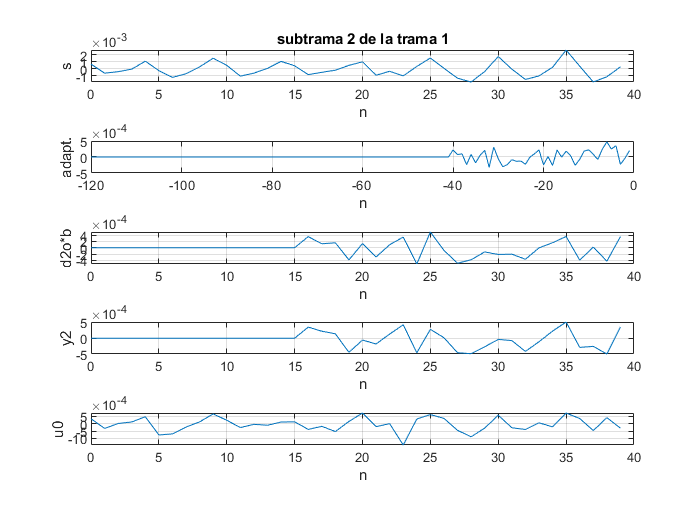

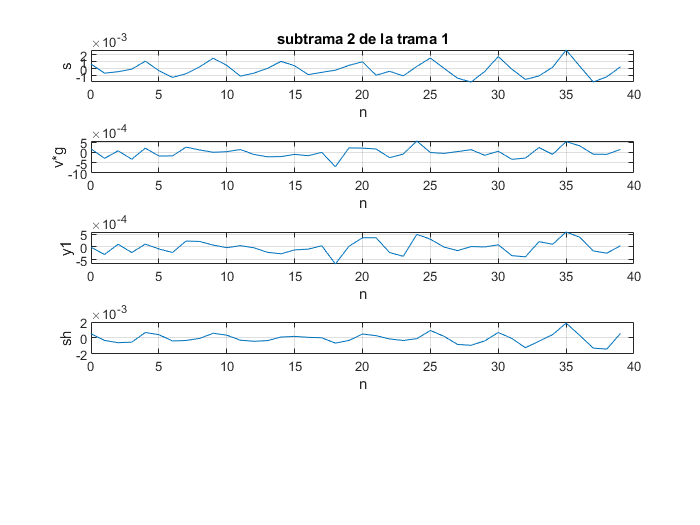

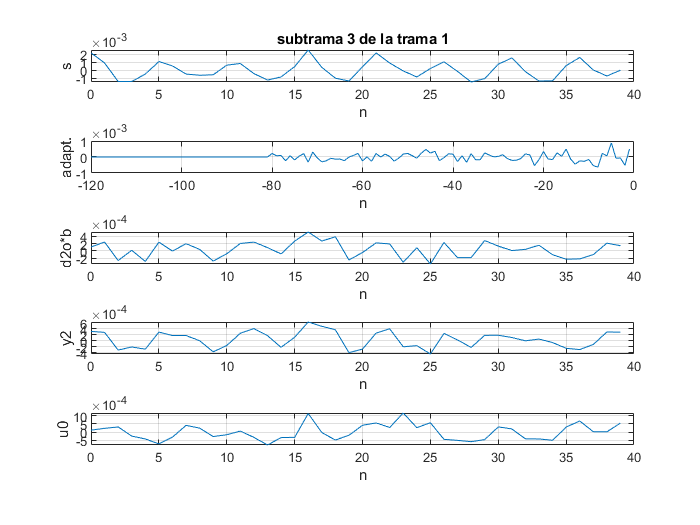

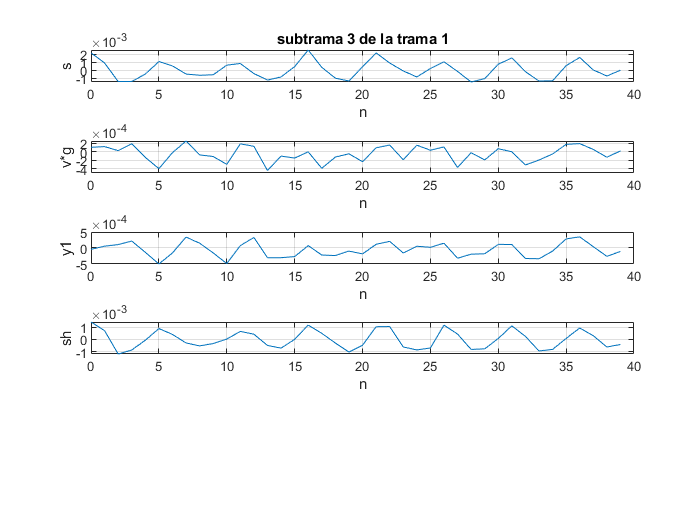

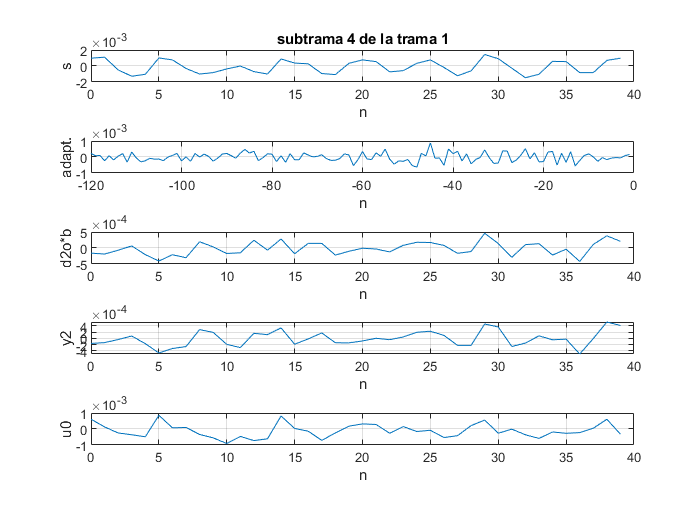

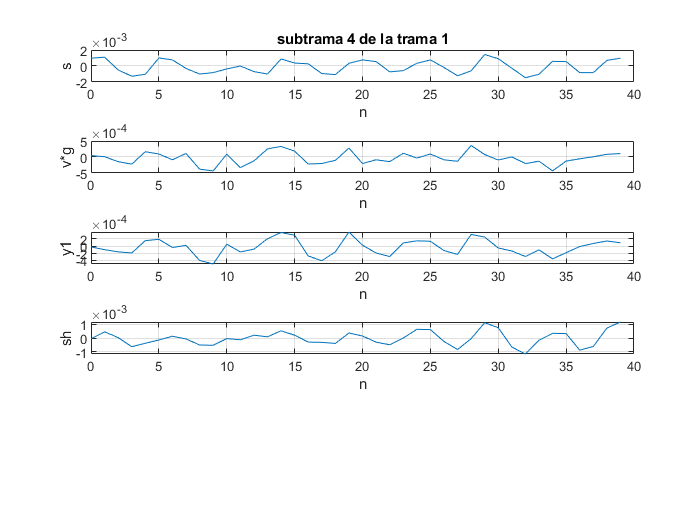

sh3 =     0.0002    0.0002    0.0001   -0.0003   -0.0001   -0.0000    0.0002    0.0003   -0.0004    0.0001    0.0001   -0.0002   -0.0002   -0.0004   -0.0000    0.0001   -0.0002   -0.0001   -0.0000    0.0004   -0.0000   -0.0003   -0.0004    0.0002    0.0004    0.0003   -0.0002   -0.0006   -0.0001    0.0005    0.0006    0.0000   -0.0006   -0.0000    0.0009    0.0008    0.0002   -0.0010   -0.0005    0.0007    0.0005   -0.0003   -0.0006   -0.0005    0.0007    0.0004   -0.0004   -0.0003   -0.0000    0.0006


B3 =          0    1.6040    1.1048   -0.8524   -1.7416    0.6552   -0.8787   -0.5402    0.9405    0.6116    0.5636   -0.6169   -0.5380   -1.1245   -0.4848   -0.7923   -0.9357   -1.2199   -1.2387    0.9955    0.4655   -0.3904    1.0172   -0.4199   -0.6544   -0.6336    0.6096    0.5208   -0.6405   -0.7831   -0.5717    0.3778   -0.8271    1.0421   -0.6060    0.4874    1.2644    0.7181   -0.5271   -0.3681   -0.6030   -0.3690    0.7399   -0.6505    0.6413    0.6402    0.8203    0.6372   -0.6457    0.8832


G3 =     0.0002   -0.0002    0.0002   -0.0002    0.0003   -0.0002    0.0005   -0.0003    0.0004   -0.0003    0.0004   -0.0003    0.0005    0.0005    0.0004    0.0005   -0.0003   -0.0008   -0.0005    0.0003    0.0004    0.0003    0.0004   -0.0004   -0.0003    0.0002    0.0003   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0001    0.0001   -0.0001   -0.0001   -0.0001   -0.0001    0.0001    0.0001   -0.0001   -0.0001    0.0001   -0.0001   -0.0001   -0.0000   -0.0001   -0.0000   -0.0001   -0.0000


AK3 =     1.0000   -0.3424    0.3414    0.3010    0.0175   -0.4223    0.2567    0.0625   -0.1797    0.1086   -0.0677    1.0000   -0.1923    0.3367    0.3455    0.0847   -0.4028    0.1441    0.0522   -0.0533   -0.0739    0.0721    1.0000   -0.2578    0.5384    0.1094    0.0931   -0.2944    0.0223   -0.0560    0.0600   -0.2040    0.1317    1.0000   -0.3525    0.7448    0.0554    0.0877   -0.3505    0.1500   -0.2491    0.1228   -0.0980    0.0506    1.0000   -0.5607    0.8536   -0.0924    0.1462   -0.4538


Tv3 =      3   -61   -55   -26   -44   -72   -73   -69   -46   -66   -64   -25   -18   -38   -75   -69   -53   -37   -31     2   -10   -41   -73   -63   -66   -36   -61   -43   -27    -5    -9   -19   -71   -37    -5     0   -16   -50   -19   -17   -17   -48   -61   -35    -9   -32   -15   -60   -53   -77


indv3 =    131   251   275   349   435   394   371   462   195   314    98   161   210    57   462   167   402    42   164   252   333   185   139   349    17   251   499   103   131    80    39    13   428   400   240   221   402     4   205   294    87   315   230   119   284   416   433   488   105   375


bitsPorMuestra2 = 0.9875

% [sh2,B2,G2,AK2,Tv2,indv2, bitsPorMuestra2] = celp(s2,Ltrama,Lsubtrama,p)
[sh3,B3,G3,AK3,Tv3,indv3, bitsPorMuestra2] = celp(s3,Ltrama,Lsubtrama,p)

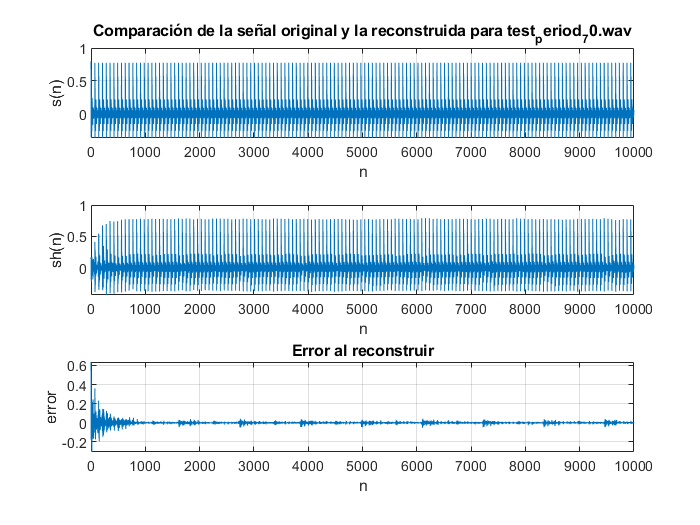

e=s(1:length(sh))-sh;

figure
subplot(311),plot(s(1:10000));xlabel('n');ylabel('s(n)'),grid,
title('Comparación de la señal original y la reconstruida' + " para " + audio1)
subplot(312), plot(sh(1:10000)); xlabel('n'); ylabel('sh(n)'), grid,
subplot(313),plot(e(1:10000)); xlabel('n'); ylabel('error'), grid,
title('Error al reconstruir')

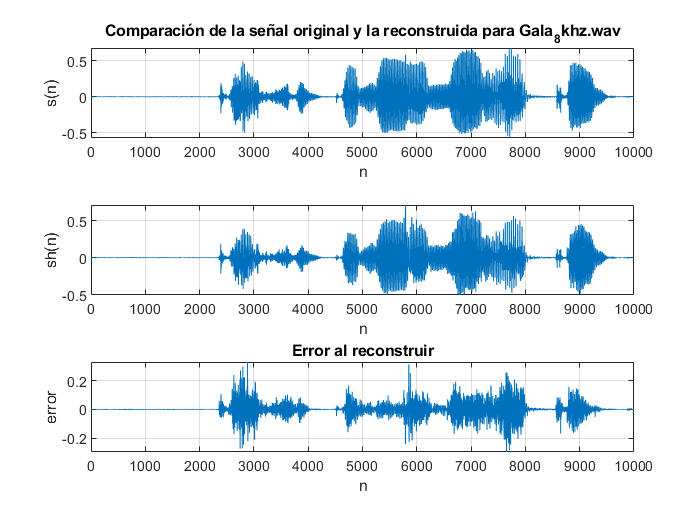

% e2=s2(1:length(sh2))-sh2;
% 
% figure
% subplot(311),plot(s2(1:10000));xlabel('n');ylabel('s(n)'),grid,
% title('Comparación de la señal original y la reconstruida' + " para " + audio2)
% subplot(312), plot(sh2(1:10000)); xlabel('n'); ylabel('sh(n)'), grid,
% subplot(313),plot(e2(1:10000)); xlabel('n'); ylabel('error'), grid,
% title('Error al reconstruir')

e3=s3(1:length(sh3))-sh3;

figure
subplot(311),plot(s3(1:10000));xlabel('n');ylabel('s(n)'),grid,
title('Comparación de la señal original y la reconstruida' + " para " + audio3)
subplot(312), plot(sh3(1:10000)); xlabel('n'); ylabel('sh(n)'), grid,
subplot(313),plot(e3(1:10000)); xlabel('n'); ylabel('error'), grid,
title('Error al reconstruir')

%sound(s3);
%sound(sh3);

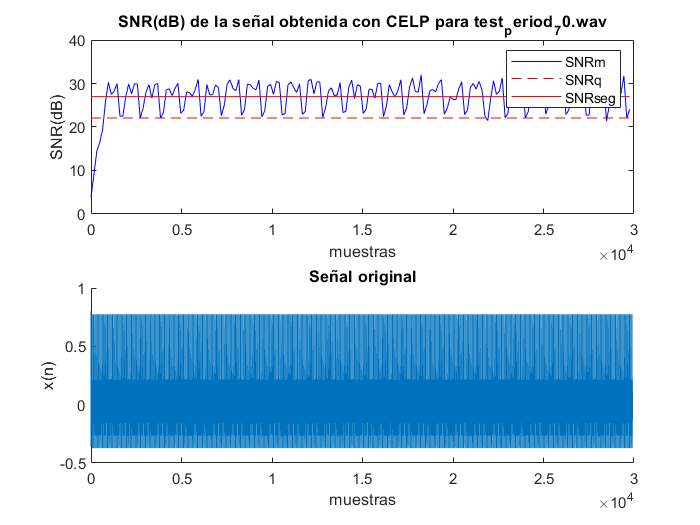

P=10;
L=160;
sa=s(1:length(sh));
SNRq = SNR(sa',sh);
[SNRseg,SNRm,m] = SNRS(sa',sh,L);
vectorsa = 1:length(sa);
figure;
%Subgrafica superior
subplot 211;
plot(m, SNRm,'b'); %SNRm riser
hold on
plot(m,ones(size(m))*(SNRq),'r--');  %SNRGlobal
plot(m,ones(size(m))*(SNRseg),'r');  %SNRSeg tread
title('SNR(dB) de la señal obtenida con CELP' + " para " + audio1);
xlabel('muestras');
ylabel('SNR(dB)');
% ylim([295 380]);
legend('SNRm','SNRq','SNRseg')
%Subgrafica inferior
subplot 212;
hold on
plot(sa); %Senal original
title('Señal original'); xlabel('muestras'); ylabel('x(n)');
hold off

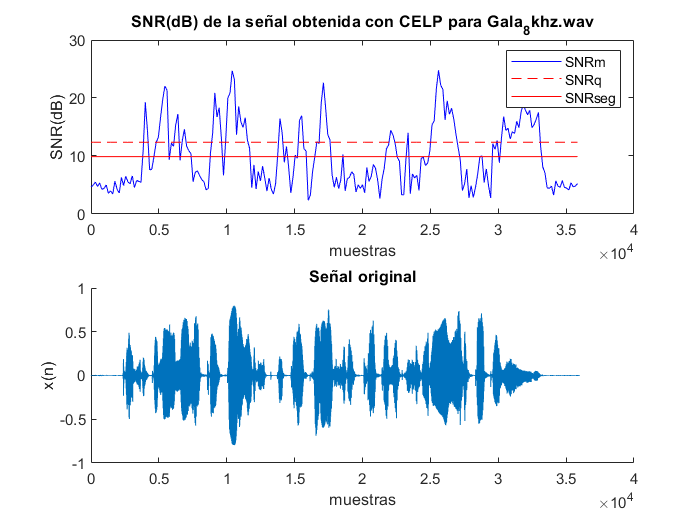

% P=10;
% L=160;
% sa2=s2(1:length(sh2));
% SNRq2 = SNR(sa2',sh2);
% [SNRseg2,SNRm2,m2] = SNRS(sa2',sh2,L);
% vectorsa2 = 1:length(sa2);
% figure;
% %Subgrafica superior
% subplot 211;
% plot(m2, SNRm2,'b'); %SNRm riser
% hold on
% plot(m2,ones(size(m2))*(SNRq2),'r--');  %SNRGlobal
% plot(m2,ones(size(m2))*(SNRseg2),'r');  %SNRSeg tread
% title('SNR(dB) de la señal obtenida con CELP' + " para " + audio2);
% xlabel('muestras');
% ylabel('SNR(dB)');
% % ylim([295 380]);
% legend('SNRm','SNRq','SNRseg')
% %Subgrafica inferior
% subplot 212;
% hold on
% plot(sa2); %Senal original
% title('Señal original'); xlabel('muestras'); ylabel('x(n)');
% hold off

P=10;
L=160;
sa3=s3(1:length(sh3));
SNRq3 = SNR(sa3',sh3);
[SNRseg3,SNRm3,m3] = SNRS(sa3',sh3,L);
vectorsa3 = 1:length(sa3);
figure;
%Subgrafica superior
subplot 211;
plot(m3, SNRm3,'b'); %SNRm riser
hold on
plot(m3,ones(size(m3))*(SNRq3),'r--');  %SNRGlobal
plot(m3,ones(size(m3))*(SNRseg3),'r');  %SNRSeg tread
title('SNR(dB) de la señal obtenida con CELP' + " para " + audio3);
xlabel('muestras');
ylabel('SNR(dB)');
% ylim([295 380]);
legend('SNRm','SNRq','SNRseg')
%Subgrafica inferior
subplot 212;
hold on
plot(sa3); %Senal original
title('Señal original'); xlabel('muestras'); ylabel('x(n)');
hold off